% Parameters
S0 = 50;                % Initial stock price
sigma = 0.40;           % Volatility (annualized)
r = 0.10;               % Risk-free rate (annualized)
T = 0.5;                % Option maturity (6 months)
N = 100;                % Number of time steps
M = 10000;              % Number of simulation paths

dt = T / N;             % Time step size
discount = exp(-r * dt);

% Simulate stock paths
randn('seed', 1); % Set seed for reproducibility
S = zeros(M, N+1);
S(:, 1) = S0;

for t = 2:N+1
    Z = randn(M, 1);
    S(:, t) = S(:, t-1) .* exp((r - 0.5 * sigma^2) * dt + sigma * sqrt(dt) .* Z);
end

% Calculate option payoff with early exercise
payoff = zeros(M, N+1);
exercise = zeros(M, N+1);

for i = 1:M
    max_S = S(i, 1); % Track the maximum stock price
    for t = 2:N+1
        max_S = max(max_S, S(i, t));
        intrinsic_value = max(max_S - S(i, t), 0); % Intrinsic value
        if intrinsic_value > 0
            payoff(i, t) = intrinsic_value;
            exercise(i, t) = 1; % Mark as exercised
        end
    end
end

% Discount to present value
option_value = max(payoff, [], 2) * discount; % Use max payoff per path
option_price = mean(option_value);           % Average over paths
option_std = std(option_value);

% Display results
fprintf('Option Price (Mean): %.4f\n', option_price);

Option Price (Mean): 15.6680


fprintf('Option Price (Std): %.4f\n', option_std);

Option Price (Std): 5.5120


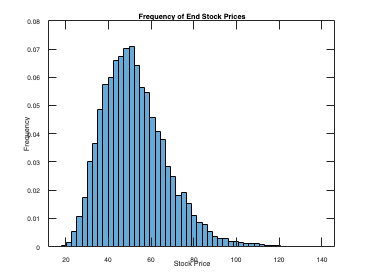


% Frequency of end stock prices and option prices
figure;
histogram(S(:, end), 50, 'Normalization', 'probability');
title('Frequency of End Stock Prices');
xlabel('Stock Price');
ylabel('Frequency');

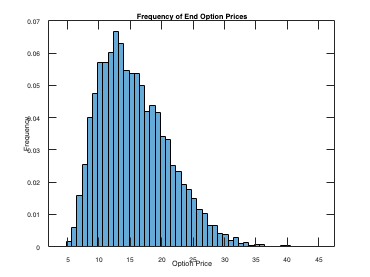


figure;
histogram(option_value, 50, 'Normalization', 'probability');
title('Frequency of End Option Prices');
xlabel('Option Price');
ylabel('Frequency');